
$$\mathrm{Part}\;i$$


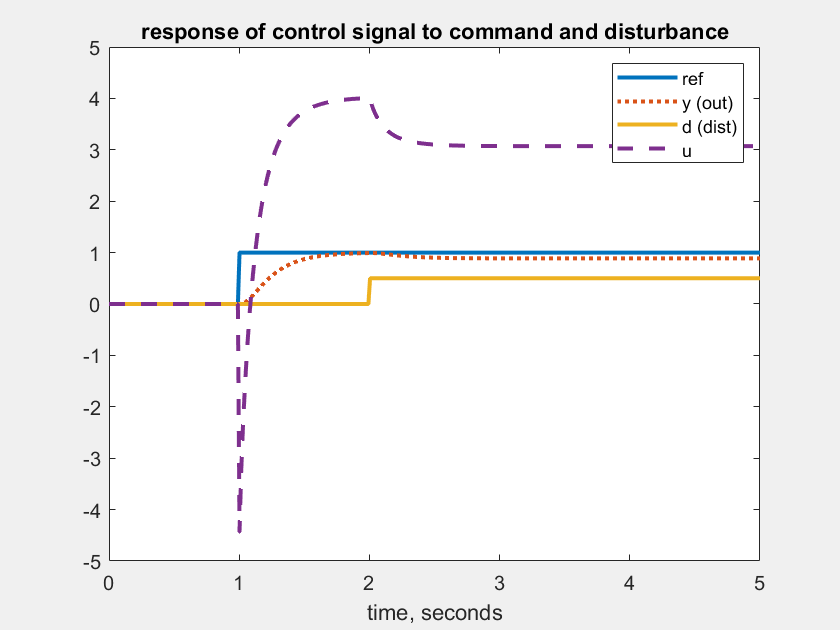

A = [0 1 0;64.4 0 -16;0 0 -100];
B = [0;0;100];
C = [1 0 0];
D = [0];
P = ss(A,B,C,D);

% disturbance description
E=B;
F=0;

% dimensions of system (makes it easier to specify closed loop
% system matrices)

n = size(A,1);    % #plant states
p = size(B,2);    % #inputs
q = size(C,1);    % #outputs
m = size(E,2);    % #disturbance states

clear r w
t = linspace(0,5,400);

for i = 1:length(t)
    % unit step command at t = 1
    if t(i) <= 1
        r(i) = 0;
    elseif t(i) >= 1
        r(i) = 1;
    end
    % 0.5 step disturbance at t = 2
    if t(i) <= 2
        d(i) = 0;
    elseif t(i) >= 2
        d(i) = .5;
%         d(i) = 0;     % uncomment this line to see the command response only
    end
end

% perform LQR design and study without observer

Q = diag([1,1,1]);
R = 5;

K = lqr(A,B,Q,R);


% precompensator gain

G = -inv(C / (A - B*K) * B);


Asf = A - B * K;
Bsf = [B*G, E]; 
Csf = C;
Dsf = [0,0]; 

Psf = ss(Asf,Bsf,Csf,Dsf);
% plot control response
Psf_u = ss(Asf,Bsf,-K,[G,0]);

% simulate response of y and u to command and disturbance
[y,x] = lsim(Psf,[r'  d'],t);
[u,x] = lsim(Psf_u,[r'  d'],t); 


figure(1)
clf
plot(t,r,'-',t,y,':',t,d,'--')
title('response of system to command and disturbance')
xlabel('time, seconds')
legend('ref','y (out)','d (dist)')
set(findall(gcf,'type','line'),'linewidth',2)

figure(2)
clf
 

plot(t,r,'-',t,y,':',t,d,'-',t,u,'--')
xlabel('time, seconds')
legend('ref','y (out)','d (dist)','u')
title('response of control signal to command and disturbance')
set(findall(gcf,'type','line'),'linewidth',2)

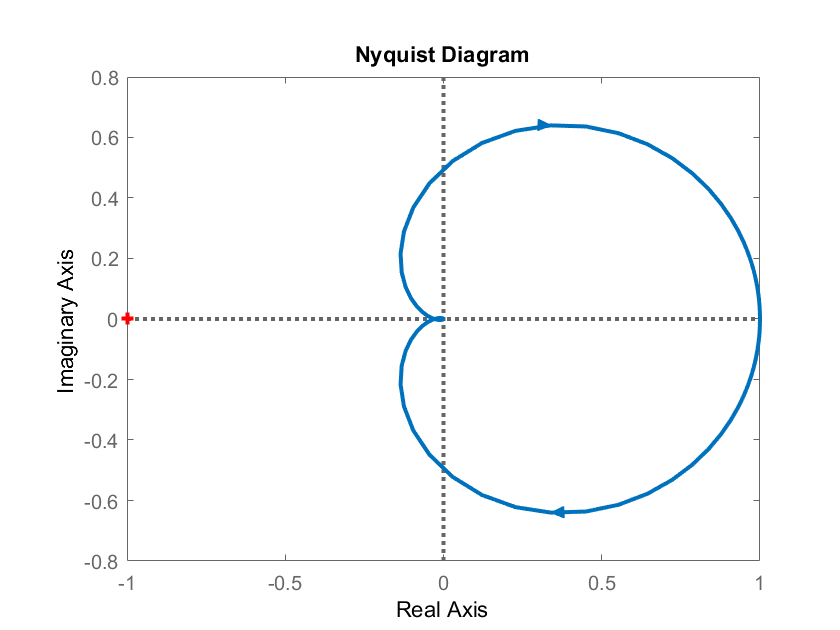

%% part (ii)

figure(3)
clf


Lsf = ss(Asf,B*G, C, 0);

nyquist(Lsf)
set(findall(gcf,'type','line'),'linewidth',2)

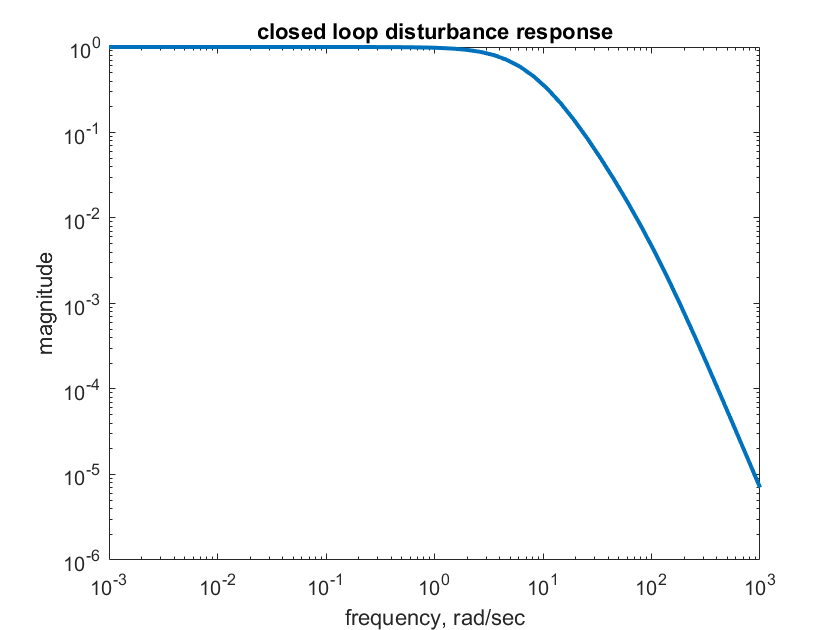


%% part (iii)

% Bode plot of closed loop disturbance response
omega = logspace(-3,3);
[mag,phase] = bode(Lsf,omega);

figure(4)
clf

loglog(squeeze(omega),squeeze(mag))
ylabel('magnitude')
xlabel('frequency, rad/sec')
title('closed loop disturbance response')
set(findall(gcf,'type','line'),'linewidth',2)



% rerun simulation in part (i) with disturbance set to 0.5 and submit Figure 1 for this part.

% part (iv)
% optimal estimator

V = 10;  % design parameters 
W =  1;
Aaug = [A,E; zeros([1,4])];
Baug = [0 0 0 1]';
Caug = [C,0];
L = lqe(Aaug,Baug,Caug,V,W);

H = -G * (C / (A - B*K) * E);

L1 = L(1:3); L2 = L(4);

L1 =    16.7843
  140.8562
   -3.1622
